# Steady heat flow across layered media

clear
set_demo_defaults()

It is instructive to consider steady heat flow across layered materials, because geological meterials are layerd at many scales. In the two limiting cases heat flow is either parallel to the layering or perpendicular to the layering.

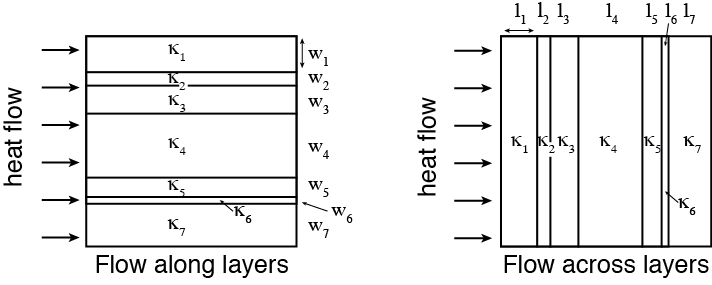

Consider a material with $N$layers, where the the n-th layer has thermal conductivity, $\kappa_n$, and width or length, $w_n$ or $l_n$, depending on flow direction. The total width or length of the material are therefore 

$W = \sum_{n=1}^N w_n $ and  $L = \sum_{n=1}^Nl_n$.

## Effective conductivities

In many materials the layering is too small scale, relative to the domain of interest, to represent it directly in the numerical discretization. Hence it is important to be able to represent the layering with effective upscaled thermal conductivities. As we will see below, these effective conductivities will depend on direction, relative to the layering.

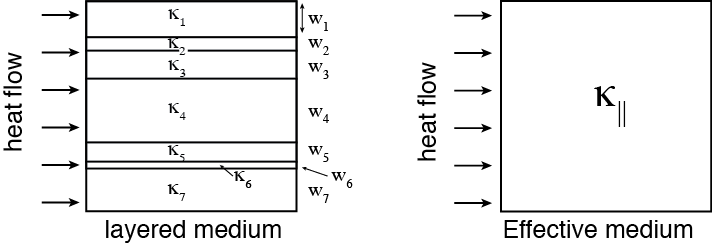

**Heat flow along the layers**

We are looking for an effective thermal conductivity, $\kappa_{\parallel}$, so that the total heat flow through the medium,$Q = W q = -W\kappa_\parallel \frac{\Delta T}{L}$, is identical to the total heat flow obtained for the layered medium with the same temperature gradient, $\Delta T/\Delta L$. In the layered medium the total heat flow is the sum of the heat flows in each layer, because the the flow is parallel to the layers:$Q = \sum_{n=1}^N w_n q_n$, where $q_n$ is the heat flux in the n-th layer. Equating these two expressions we obtain

$W\kappa_\parallel = \sum_{n=1}^Nw_n\kappa_n$, so that the effective flux is given by $\kappa_\parallel = \sum_{n=1}^N\frac{w_n}{W}\kappa_n$. Hence, the effective thermal conductivity for heat flow along layers is the fractional width weighted **arithmetic mean** of the conductivities of the individual layers.

**Heat flow across the layers**

Now let's develop an analogous expression the effective thermal conductivity, $\kappa_\perp$, for heat flow across the layers. In this case the heat flux across each payer must be identical, $q = q_n = -\kappa_n \Delta T_n/l_n$, but the temperature gradient across each layer$\Delta T_n/l_n$, will be different. The total temperature drop and the total medium length are then given by

$\Delta T = \sum_{n=1}^N \Delta T_n$, and $L = \sum_{n=1}^Nl_n$. 

Substituing the first into the expression for the heat flux in terms of the effective conductivity we get


$$q = -\kappa_\perp\frac{\sum_{n=1}^N \Delta T_n}{L}$$


now we use the expression for the heat flux across each layer to eliminate the temperature drops and obtain

$qL=-\kappa_\perp \sum_{n=1}^N \left(-\frac{ql_n}{\kappa_n}\right)$,

where $q$cancels and we re arrange to obtain the following expression the effective thermal conductivity across layers:


$$\kappa_\perp = \frac{1}{\sum_{n=1}^N\frac{l_n/L}{\kappa_n}}$$


This is called the harmonic average, and again it is weighted by the length fraction, $l_n/L$, of each layer.

## General Power-law average

These two averages are special cases of the general power-paw average, given by


$$\langle\kappa\rangle_p = \left(\frac{1}{N}\sum_{n=1}^N(\kappa_n)^p\right)^{1/p}$$


where the arithmetic average is recovered for p=1 and the harmonic average for p=-1.  

(Note to self - still need to work out the weighting!)

## Numerical examples

Note: This requires 2D operators, which you don't have yet.

kappa_vec = [30;100;30;75;350; 5;120];
dist_vec =  [10; 35; 5;15;  5;20; 10];
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 100;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = 100;
Grid = build_grid(Grid); 
[D,G,I] = build_ops(Grid);
L = @(Kd) -D*Kd*G; fs = zeros(Grid.N,1);
BC.dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.g = [ones(Grid.Ny,1);zeros(Grid.Ny,1)];
BC.dof_neu = []; BC.dof_f_neu = []; BC.qb = [];
[B,N,fn] = build_bnd(BC,Grid,I);

First let's look at heat flow along the layers

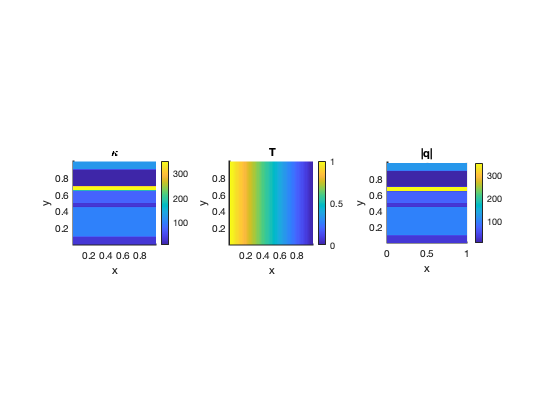

[Kd_x,K_x] = make_layered_medium(kappa_vec,dist_vec,Grid,'x-dir');
u = solve_lbvp(L(Kd_x),fs+fn,B,BC.g,N);
q = comp_flux(D,Kd_x,G,u,fs,Grid,BC);

subplot 131
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
surf(Xc,Yc,K_x), shading interp, view(2), colorbar
xlabel 'x', ylabel 'y', title '\kappa'
axis square tight

subplot 132
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
surf(Xc,Yc,reshape(u,Grid.Ny,Grid.Nx)), shading interp, view(2), colorbar
xlabel 'x', ylabel 'y', title 'T'
axis square tight

subplot 133
[Xx,Yx] = meshgrid(Grid.xf,Grid.yc);
surf(Xx,Yx,reshape(q(1:Grid.Nfx),Grid.Ny,Grid.Nx+1)), shading interp, view(2), colorbar
xlabel 'x', ylabel 'y', title '|q|'
axis square tight

Now compare the heat flow computed numerically on the layered medium with the effectiv expression

Qnum = q(Grid.dof_f_xmin)'*Grid.A(Grid.dof_f_xmin)

Qnum = 82.0707

kappa_eff = (dist_vec/100)'*kappa_vec;
Qeff = kappa_eff*1/(1-Grid.dx)

Qeff = 82.0707

Then look at heat flow across the layers

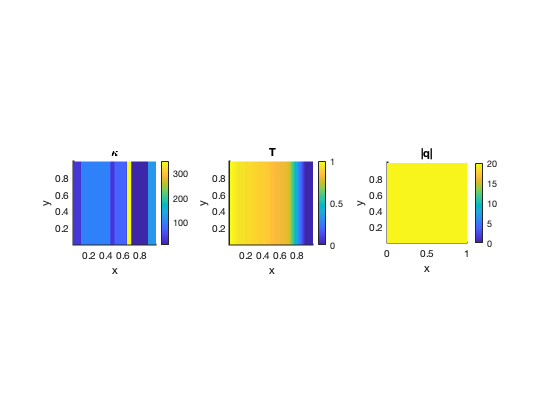

[Kd_y,K_y] = make_layered_medium(kappa_vec,dist_vec,Grid,'y-dir');
u = solve_lbvp(L(Kd_y),fs+fn,B,BC.g,N);
q = comp_flux(D,Kd_y,G,u,fs,Grid,BC);

subplot 131
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
surf(Xc,Yc,K_y), shading interp, view(2), colorbar
xlabel 'x', ylabel 'y', title '\kappa'
axis square tight

subplot 132
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
surf(Xc,Yc,reshape(u,Grid.Ny,Grid.Nx)), shading interp, view(2), colorbar
xlabel 'x', ylabel 'y', title 'T'
axis square tight

subplot 133
[Xx,Yx] = meshgrid(Grid.xf,Grid.yc);
surf(Xx,Yx,reshape(q(1:Grid.Nfx),Grid.Ny,Grid.Nx+1)), shading interp, view(2), colorbar
caxis([0 20])
xlabel 'x', ylabel 'y', title '|q|'
axis square tight

Now compare the heat flux computed directly on the layers medium with the effective expression

qnum = q(1)

qnum = 19.5054

kappa_eff = 100./sum((dist_vec./kappa_vec));
qeff = kappa_eff*1/(1-Grid.dx)

qeff = 19.6227

## Auxillary functions

function [Kd,K] = make_layered_medium(kappa,dist,Grid,orientation)
if length(kappa) ~=length(dist); error('kappa and dist not same length\n'); end
K = ones(Grid.Ny,Grid.Nx);
if strcmp(orientation,'x-dir')
    K([1:dist(1)],:) = kappa(1);
    for i=2:length(kappa)
        K(sum(dist(1:i-1))+1:sum(dist(1:i)),:) = kappa(i);
    end
else
    K(:,[1:dist(1)]) = kappa(1);
    for i=2:length(kappa)
        K(:,sum(dist(1:i-1))+1:sum(dist(1:i))) = kappa(i);
    end
end

Kd = comp_mean(K,-1,1,Grid);
end